# **Linear and (almost) nonlinear controllers for a unicycle **	 

%% Unicycle trajectory planning following a Bernoulli lemniscate
 close all; 
 clc;
 
%% Parameters
alpha = 4;      % Last matriculation number
r1 = 2;   
r2=0.2;
current_r = r1;
%current_r = r2;
a = alpha+1;
Tf = 4*pi/a;     % Final time
dt = 0.01;          
t = 0:dt:Tf;     % Time vector
t = t(:);                
num_points = length(t);  

%% Desired trajectory computation
lemniscate_x = @(t, r) r*cos(a*t)./(1 + sin(a*t).^2);
lemniscate_y = @(t, r) r*cos(a*t).*sin(a*t)./(1 + sin(a*t).^2);
 
% Desired positions
xd = zeros(num_points, 1);
yd = zeros(num_points, 1);
 
for i = 1:num_points
    xd(i) = lemniscate_x(t(i), current_r);
    yd(i) = lemniscate_y(t(i), current_r);
end
 
%% Derivatives
 
xd_dot = gradient(xd, dt);
yd_dot = gradient(yd, dt);
 
% Desired orientation
thetad = atan2(yd_dot, xd_dot);
 
% unwrap application to avoid discotinuity
thetad = unwrap(thetad);
 
% thetad derivative 
thetad_dot = gradient(thetad, dt);
 
%% Desired linear and angular velocities
vd = sqrt(xd_dot.^2 + yd_dot.^2);
omegad = thetad_dot;

 
% timeseries creation for each signal
xd_tms = timeseries(xd, t, 'Name', 'Desired x Position');
yd_tms = timeseries(yd, t, 'Name', 'Desired y Position');
thetad_tms = timeseries(thetad, t, 'Name', 'Desired Orientation');
xd_dot_tms = timeseries(xd_dot, t, 'Name', 'Desired x Velocity');
yd_dot_tms = timeseries(yd_dot, t, 'Name', 'Desired y Velocity');
thetad_dot_tms = timeseries(thetad_dot, t, 'Name', 'Desired Angular Velocity');
vd_tms = timeseries(vd, t, 'Name', 'Desired Linear Velocity');
omegad_tms = timeseries(omegad, t, 'Name', 'Desired Angular Velocity');
 

%% Initial conditions
 
% Initial desired positions (t=0)
xd_init = lemniscate_x(0, current_r);
yd_init = lemniscate_y(0, current_r);
 
% Initial desired orientation
thetad_init = atan2(yd_dot(1), xd_dot(1));
 
% Generate random initial position (within 0.5m of desired position)
rng(42); 
x0 = xd_init + (rand-0.5);
y0 = yd_init + (rand-0.5);
theta0 = thetad_init + (rand-0.5);
 
% Ensure that initial position is within 0.5m
while norm([x0-xd_init, y0-yd_init]) > 0.5
    x0 = xd_init + (rand-0.5);
    y0 = yd_init + (rand-0.5);
end
 
% Initial state vector 
initial_state = [x0; y0; theta0];

%% Simulink simulation start 
modelName = 'Point_3';
open_system(modelName);

% Simulation parameters
set_param(modelName, 'StopTime', num2str(Tf));
set_param(modelName, 'FixedStep', num2str(dt));

% Simulation exection 
simOut = sim(modelName);

% Simulation time
t_sim = simOut.tout;

% Toworkspace
% Linear controller
xl = simOut.xl.signals.values;
yl = simOut.yl.signals.values;
thetal = simOut.thetal.signals.values;
v_l = simOut.v_l.signals.values;
omega_l = simOut.omega_l.signals.values;
e_xl = simOut.e_xl.signals.values;
e_yl = simOut.e_yl.signals.values;
e_thetal = simOut.e_thetal.signals.values;

% Nonlinear controller
xnl = simOut.xnl.signals.values;
ynl = simOut.ynl.signals.values;
thetanl = simOut.thetanl.signals.values;
v_nl = simOut.v_nl.signals.values;
omega_nl = simOut.omega_nl.signals.values;
e_xnl = simOut.e_xnl.signals.values;
e_ynl = simOut.e_ynl.signals.values;
e_thetanl = simOut.e_thetanl.signals.values;

%% Plots setting
fontSize = 11;
titleSize = 12;
legendSize = 10;
lineWidth_desired = 2;
lineWidth_linear = 2;
lineWidth_nonlinear = 2;

PLOTS for r=0.2

if (current_r == r2)
    r_value = r2;
    suffix = '_r2';
    
    %% 1) First figure: Position tracking
figure('Color', 'white', 'Position', [100 100 800 650]);  

% Subplot for linear x
subplot(2,2,1);
plot(t, xd, 'Color', [0.7 0 0], 'LineWidth', lineWidth_desired, 'LineStyle', '-');
hold on;
plot(t_sim, xl, 'Color', [0 0 1], 'LineWidth', lineWidth_linear);
title('\textbf{Linear $x$ tracking}', 'FontSize', titleSize, 'Interpreter', 'latex');
xlabel('\textbf{$t$ [s]}', 'FontSize', fontSize, 'Interpreter', 'latex');
ylabel('\textbf{$x$ [m]}', 'FontSize', fontSize, 'Interpreter', 'latex');
legend({'$x_d$', '$x_l$'}, 'FontSize', legendSize, 'Interpreter', 'latex', 'Location', 'southeast');
grid on;
set(gca, 'FontSize', fontSize);
ylim([-0.5 0.5]);
xlim([0 Tf+0.1]);

pos = get(gca, 'Position');
set(gca, 'Position', [pos(1), pos(2)-0.03, pos(3), pos(4)]);

% Subplot for nonlinear x
subplot(2,2,2);
plot(t, xd, 'Color', [0.7 0 0], 'LineWidth', lineWidth_desired, 'LineStyle', '-');
hold on;
plot(t_sim, xnl, 'Color', [0 0 1], 'LineWidth', lineWidth_nonlinear);
title('\textbf{Nonlinear $x$ tracking}', 'FontSize', titleSize, 'Interpreter', 'latex');
xlabel('\textbf{$t$ [s]}', 'FontSize', fontSize, 'Interpreter', 'latex');
ylabel('\textbf{$x$ [m]}', 'FontSize', fontSize, 'Interpreter', 'latex');
legend({'$x_d$', '$x_{nl}$'}, 'FontSize', legendSize, 'Interpreter', 'latex', 'Location', 'southeast');
grid on;
set(gca, 'FontSize', fontSize);
ylim([-0.5 0.5]);
xlim([0 Tf+0.1]);

pos = get(gca, 'Position');
set(gca, 'Position', [pos(1)-0.03, pos(2)-0.03, pos(3), pos(4)]);

% Subplot for linear y
subplot(2,2,3);
plot(t, yd, 'Color', [0.7 0 0], 'LineWidth', lineWidth_desired, 'LineStyle', '-');
hold on;
plot(t_sim, yl, 'Color', [0 0 1], 'LineWidth', lineWidth_linear);
title('\textbf{Linear $y$ tracking}', 'FontSize', titleSize, 'Interpreter', 'latex');
xlabel('\textbf{$t$ [s]}', 'FontSize', fontSize, 'Interpreter', 'latex');
ylabel('\textbf{$y$ [m]}', 'FontSize', fontSize, 'Interpreter', 'latex');
legend({'$y_d$', '$y_l$'}, 'FontSize', legendSize, 'Interpreter', 'latex', 'Location', 'southeast');
grid on;
set(gca, 'FontSize', fontSize);
ylim([-0.5 0.5]);
xlim([0 Tf+0.1]);

pos = get(gca, 'Position');
set(gca, 'Position', [pos(1), pos(2)-0.03, pos(3), pos(4)]);

% Subplot for nonlinear y
subplot(2,2,4);
plot(t, yd, 'Color', [0.7 0 0], 'LineWidth', lineWidth_desired, 'LineStyle', '-');
hold on;
plot(t_sim, ynl, 'Color', [0 0 1], 'LineWidth', lineWidth_nonlinear);
title('\textbf{Nonlinear $y$ tracking}', 'FontSize', titleSize, 'Interpreter', 'latex');
xlabel('\textbf{$t$ [s]}', 'FontSize', fontSize, 'Interpreter', 'latex');
ylabel('\textbf{$y$ [m]}', 'FontSize', fontSize, 'Interpreter', 'latex');
legend({'$y_d$', '$y_{nl}$'}, 'FontSize', legendSize, 'Interpreter', 'latex', 'Location', 'southeast');
grid on;
set(gca, 'FontSize', fontSize);
ylim([-0.5 0.5]);
xlim([0 Tf+0.1]);

pos = get(gca, 'Position');
set(gca, 'Position', [pos(1)-0.03, pos(2)-0.03, pos(3), pos(4)]);

sgt = sgtitle(['\textbf{Position tracking for $r = ', num2str(r_value), '$}'], 'FontSize', titleSize+2, 'Interpreter', 'latex');
saveas(gcf, ['position_tracking', suffix, '.eps'], 'epsc');

%% 2) Second figure: Position errors
figure('Color', 'white', 'Position', [100 100 800 450]);  

% Subplot for x errors
subplot(1,2,1);
plot(t_sim, e_xl, 'Color', [0.8, 0.6, 0], 'LineWidth', lineWidth_linear);
hold on;
plot(t_sim, e_xnl, 'Color', [0 0 1], 'LineWidth', lineWidth_nonlinear);
title('\textbf{$x$ errors}', 'FontSize', titleSize, 'Interpreter', 'latex');
xlabel('\textbf{$t$ [s]}', 'FontSize', fontSize, 'Interpreter', 'latex');
ylabel('\textbf{$e_x$ [m]}', 'FontSize', fontSize, 'Interpreter', 'latex');
legend({'$e_{x,l}$', '$e_{x,nl}$'}, 'FontSize', legendSize, 'Interpreter', 'latex', 'Location', 'southeast');
grid on;
set(gca, 'FontSize', fontSize);
xlim([0 Tf+0.1]);
ylim([-0.5 0.3]); 

pos = get(gca, 'Position');
set(gca, 'Position', [pos(1), pos(2)-0.02, pos(3), pos(4)]);

% Subplot for y errors
subplot(1,2,2);
plot(t_sim, e_yl, 'Color', [0.8, 0.6, 0], 'LineWidth', lineWidth_linear);
hold on;
plot(t_sim, e_ynl, 'Color', [0 0 1], 'LineWidth', lineWidth_nonlinear);
title('\textbf{$y$ errors}', 'FontSize', titleSize, 'Interpreter', 'latex');
xlabel('\textbf{$t$ [s]}', 'FontSize', fontSize, 'Interpreter', 'latex');
ylabel('\textbf{$e_y$ [m]}', 'FontSize', fontSize, 'Interpreter', 'latex');
legend({'$e_{y,l}$', '$e_{y,nl}$'}, 'FontSize', legendSize, 'Interpreter', 'latex', 'Location', 'southeast');
grid on;
set(gca, 'FontSize', fontSize);
xlim([0 Tf+0.1]);
ylim([-0.5 0.3]); 

pos = get(gca, 'Position');
set(gca, 'Position', [pos(1)-0.03, pos(2)-0.02, pos(3), pos(4)]);

sgtitle(['\textbf{Position errors for $r = ', num2str(r_value), '$}'], 'FontSize', titleSize+2, 'Interpreter', 'latex');
saveas(gcf, ['position_errors', suffix, '.eps'], 'epsc');

%% 3) Third figure: Velocities
figure('Color', 'white', 'Position', [100 100 800 650]);  

% Subplot for linear velocity (linear control)
subplot(2,2,1);
%plot(t, vd, 'Color', [0.7 0 0], 'LineWidth', lineWidth_desired);
%hold on;
plot(t_sim, v_l, 'Color', [0 0 0], 'LineWidth', lineWidth_linear);
title('\textbf{Linear velocity (linear control)}', 'FontSize', titleSize, 'Interpreter', 'latex');
xlabel('\textbf{$t$ [s]}', 'FontSize', fontSize, 'Interpreter', 'latex');
ylabel('\textbf{$v$ [m/s]}', 'FontSize', fontSize, 'Interpreter', 'latex');
legend({'$v_l$'}, 'FontSize', legendSize, 'Interpreter', 'latex', 'Location', 'southeast');
grid on;
set(gca, 'FontSize', fontSize);
xlim([0 Tf+0.1]);
ylim([-1.5 2]); 

pos = get(gca, 'Position');
set(gca, 'Position', [pos(1), pos(2)-0.03, pos(3), pos(4)]);

% Subplot for angular velocity (linear control)
subplot(2,2,3);
%plot(t, omegad, 'Color', [0.7 0 0], 'LineWidth', lineWidth_desired);
%hold on;
plot(t_sim, omega_l, 'Color', [0 0 1], 'LineWidth', lineWidth_linear);
title('\textbf{Angular velocity (linear control)}', 'FontSize', titleSize, 'Interpreter', 'latex');
xlabel('\textbf{$t$ [s]}', 'FontSize', fontSize, 'Interpreter', 'latex');
ylabel('\textbf{$\omega$ [rad/s]}', 'FontSize', fontSize, 'Interpreter', 'latex');
legend({'$\omega_l$'}, 'FontSize', legendSize, 'Interpreter', 'latex', 'Location', 'southeast');
grid on;
set(gca, 'FontSize', fontSize);
xlim([0 Tf+0.1]);
ylim([-20 20]); 
 
pos = get(gca, 'Position');
set(gca, 'Position', [pos(1), pos(2)-0.03, pos(3), pos(4)]);

% Subplot for linear velocity (nonlinear control)
subplot(2,2,2);
%plot(t, vd, 'Color', [0.7 0 0], 'LineWidth', lineWidth_desired);
%hold on;
plot(t_sim, v_nl, 'Color', [0 0 0], 'LineWidth', lineWidth_nonlinear);
title('\textbf{Linear velocity (nonlinear control)}', 'FontSize', titleSize, 'Interpreter', 'latex');
xlabel('\textbf{$t$ [s]}', 'FontSize', fontSize, 'Interpreter', 'latex');
ylabel('\textbf{$v$ [m/s]}', 'FontSize', fontSize, 'Interpreter', 'latex');
legend({'$v_{nl}$'}, 'FontSize', legendSize, 'Interpreter', 'latex', 'Location', 'southeast');
grid on;
set(gca, 'FontSize', fontSize);
xlim([0 Tf+0.1]);
ylim([-1.5 2]); 

pos = get(gca, 'Position');
set(gca, 'Position', [pos(1)-0.03, pos(2)-0.03, pos(3), pos(4)]);

% Subplot for angular velocity (nonlinear control)
subplot(2,2,4);
%plot(t, omegad, 'Color', [0.7 0 0], 'LineWidth', lineWidth_desired);
%hold on;
plot(t_sim, omega_nl, 'Color', [0 0 1], 'LineWidth', lineWidth_nonlinear);
title('\textbf{Angular velocity (nonlinear control)}', 'FontSize', titleSize, 'Interpreter', 'latex');
xlabel('\textbf{$t$ [s]}', 'FontSize', fontSize, 'Interpreter', 'latex');
ylabel('\textbf{$\omega$ [rad/s]}', 'FontSize', fontSize, 'Interpreter', 'latex');
legend({'$\omega_{nl}$'}, 'FontSize', legendSize, 'Interpreter', 'latex', 'Location', 'southeast');
grid on;
set(gca, 'FontSize', fontSize);
xlim([0 Tf+0.1]);
ylim([-20 20]); 

pos = get(gca, 'Position');
set(gca, 'Position', [pos(1)-0.03, pos(2)-0.03, pos(3), pos(4)]);

sgtitle(['\textbf{Velocities for $r = ', num2str(r_value), '$}'], 'FontSize', titleSize+2, 'Interpreter', 'latex');
saveas(gcf, ['velocities', suffix, '.eps'], 'epsc');

PLOTS for r=2

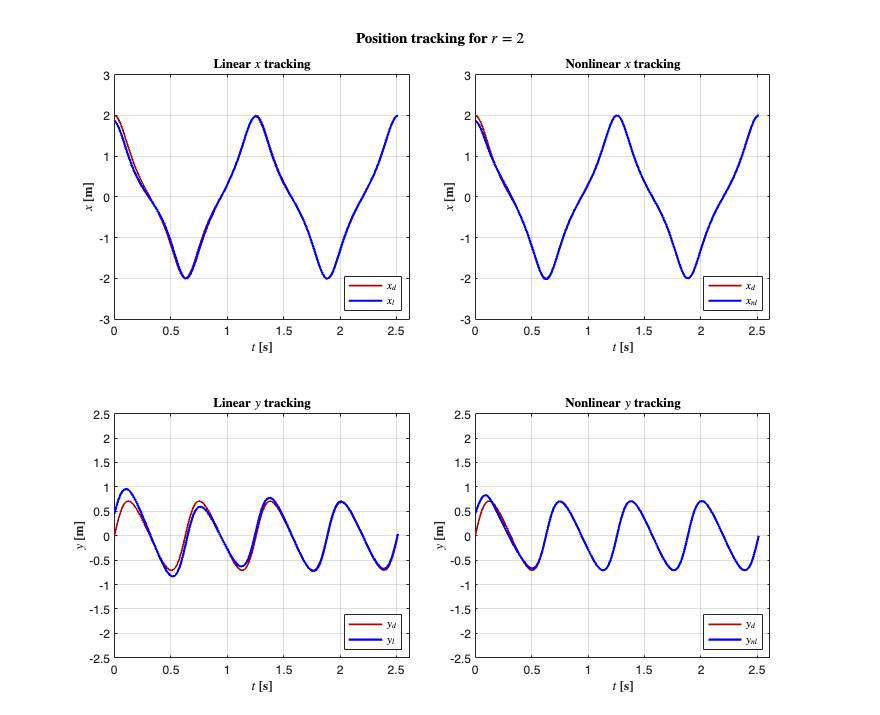

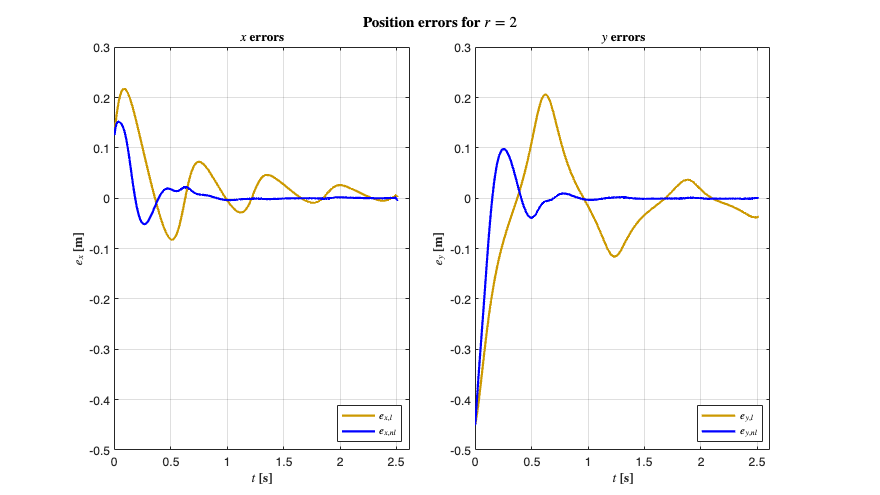

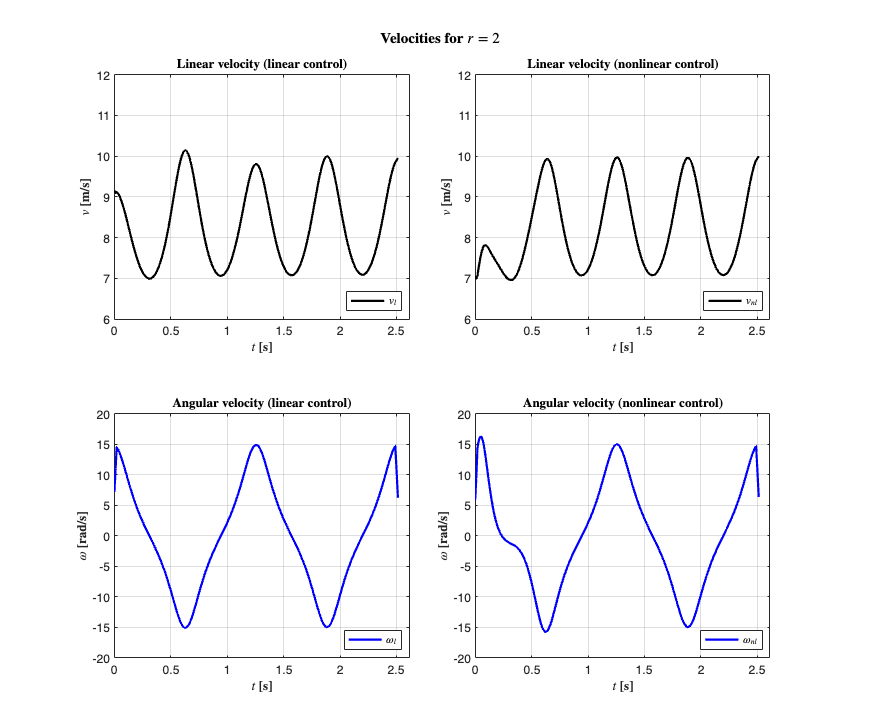

else
    r_value = r1;
    suffix = '_r1';

   %% 1) First figure: Position tracking
figure('Color', 'white', 'Position', [100 100 800 650]);  

% Subplot for linear x
subplot(2,2,1);
plot(t, xd, 'Color', [0.7 0 0], 'LineWidth', lineWidth_desired, 'LineStyle', '-');
hold on;
plot(t_sim, xl, 'Color', [0 0 1], 'LineWidth', lineWidth_linear);
title('\textbf{Linear $x$ tracking}', 'FontSize', titleSize, 'Interpreter', 'latex');
xlabel('\textbf{$t$ [s]}', 'FontSize', fontSize, 'Interpreter', 'latex');
ylabel('\textbf{$x$ [m]}', 'FontSize', fontSize, 'Interpreter', 'latex');
legend({'$x_d$', '$x_l$'}, 'FontSize', legendSize, 'Interpreter', 'latex', 'Location', 'southeast');
grid on;
set(gca, 'FontSize', fontSize);
ylim([-3 3]);
xlim([0 Tf+0.1]);
 
pos = get(gca, 'Position');
set(gca, 'Position', [pos(1), pos(2)-0.03, pos(3), pos(4)]);

% Subplot for nonlinear x
subplot(2,2,2);
plot(t, xd, 'Color', [0.7 0 0], 'LineWidth', lineWidth_desired, 'LineStyle', '-');
hold on;
plot(t_sim, xnl, 'Color', [0 0 1], 'LineWidth', lineWidth_nonlinear);
title('\textbf{Nonlinear $x$ tracking}', 'FontSize', titleSize, 'Interpreter', 'latex');
xlabel('\textbf{$t$ [s]}', 'FontSize', fontSize, 'Interpreter', 'latex');
ylabel('\textbf{$x$ [m]}', 'FontSize', fontSize, 'Interpreter', 'latex');
legend({'$x_d$', '$x_{nl}$'}, 'FontSize', legendSize, 'Interpreter', 'latex', 'Location', 'southeast');
grid on;
set(gca, 'FontSize', fontSize);
xlim([0 Tf+0.1]);
ylim([-3 3]);

pos = get(gca, 'Position');
set(gca, 'Position', [pos(1)-0.03, pos(2)-0.03, pos(3), pos(4)]);

% Subplot for linear y
subplot(2,2,3);
plot(t, yd, 'Color', [0.7 0 0], 'LineWidth', lineWidth_desired, 'LineStyle', '-');
hold on;
plot(t_sim, yl, 'Color', [0 0 1], 'LineWidth', lineWidth_linear);
title('\textbf{Linear $y$ tracking}', 'FontSize', titleSize, 'Interpreter', 'latex');
xlabel('\textbf{$t$ [s]}', 'FontSize', fontSize, 'Interpreter', 'latex');
ylabel('\textbf{$y$ [m]}', 'FontSize', fontSize, 'Interpreter', 'latex');
legend({'$y_d$', '$y_l$'}, 'FontSize', legendSize, 'Interpreter', 'latex', 'Location', 'southeast');
grid on;
set(gca, 'FontSize', fontSize);
ylim([-2.5 2.5]);
xlim([0 Tf+0.1]);

pos = get(gca, 'Position');
set(gca, 'Position', [pos(1), pos(2)-0.03, pos(3), pos(4)]);

% Subplot for nonlinear y
subplot(2,2,4);
plot(t, yd, 'Color', [0.7 0 0], 'LineWidth', lineWidth_desired, 'LineStyle', '-');
hold on;
plot(t_sim, ynl, 'Color', [0 0 1], 'LineWidth', lineWidth_nonlinear);
title('\textbf{Nonlinear $y$ tracking}', 'FontSize', titleSize, 'Interpreter', 'latex');
xlabel('\textbf{$t$ [s]}', 'FontSize', fontSize, 'Interpreter', 'latex');
ylabel('\textbf{$y$ [m]}', 'FontSize', fontSize, 'Interpreter', 'latex');
legend({'$y_d$', '$y_{nl}$'}, 'FontSize', legendSize, 'Interpreter', 'latex', 'Location', 'southeast');
grid on;
set(gca, 'FontSize', fontSize);
ylim([-2.5 2.5]);
xlim([0 Tf+0.1]);

pos = get(gca, 'Position');
set(gca, 'Position', [pos(1)-0.03, pos(2)-0.03, pos(3), pos(4)]);

sgt = sgtitle(['\textbf{Position tracking for $r = ', num2str(r_value), '$}'], 'FontSize', titleSize+2, 'Interpreter', 'latex');

saveas(gcf, ['position_tracking', suffix, '.eps'], 'epsc');

%% 2) Second figure: Position errors
figure('Color', 'white', 'Position', [100 100 800 450]);  

% Subplot for x errors
subplot(1,2,1);
plot(t_sim, e_xl, 'Color', [0.8, 0.6, 0], 'LineWidth', lineWidth_linear);
hold on;
plot(t_sim, e_xnl, 'Color', [0 0 1], 'LineWidth', lineWidth_nonlinear);
title('\textbf{$x$ errors}', 'FontSize', titleSize, 'Interpreter', 'latex');
xlabel('\textbf{$t$ [s]}', 'FontSize', fontSize, 'Interpreter', 'latex');
ylabel('\textbf{$e_x$ [m]}', 'FontSize', fontSize, 'Interpreter', 'latex');
legend({'$e_{x,l}$', '$e_{x,nl}$'}, 'FontSize', legendSize, 'Interpreter', 'latex', 'Location', 'southeast');
grid on;
set(gca, 'FontSize', fontSize);
xlim([0 Tf+0.1]);
ylim([-0.5 0.3]); 

pos = get(gca, 'Position');
set(gca, 'Position', [pos(1), pos(2)-0.02, pos(3), pos(4)]);

% Subplot for y errors
subplot(1,2,2);
plot(t_sim, e_yl, 'Color', [0.8, 0.6, 0], 'LineWidth', lineWidth_linear);
hold on;
plot(t_sim, e_ynl, 'Color', [0 0 1], 'LineWidth', lineWidth_nonlinear);
title('\textbf{$y$ errors}', 'FontSize', titleSize, 'Interpreter', 'latex');
xlabel('\textbf{$t$ [s]}', 'FontSize', fontSize, 'Interpreter', 'latex');
ylabel('\textbf{$e_y$ [m]}', 'FontSize', fontSize, 'Interpreter', 'latex');
legend({'$e_{y,l}$', '$e_{y,nl}$'}, 'FontSize', legendSize, 'Interpreter', 'latex', 'Location', 'southeast');
grid on;
set(gca, 'FontSize', fontSize);
xlim([0 Tf+0.1]);
ylim([-0.5 0.3]); 

pos = get(gca, 'Position');
set(gca, 'Position', [pos(1)-0.03, pos(2)-0.02, pos(3), pos(4)]);

sgtitle(['\textbf{Position errors for $r = ', num2str(r_value), '$}'], 'FontSize', titleSize+2, 'Interpreter', 'latex');
saveas(gcf, ['position_errors', suffix, '.eps'], 'epsc');

%% 3) Third figure: Velocities
figure('Color', 'white', 'Position', [100 100 800 650]);  

% Subplot for linear velocity (linear control)
subplot(2,2,1);
%plot(t, vd, 'Color', [0.7 0 0], 'LineWidth', lineWidth_desired);
%hold on;
plot(t_sim, v_l, 'Color', [0 0 0], 'LineWidth', lineWidth_linear);
title('\textbf{Linear velocity (linear control)}', 'FontSize', titleSize, 'Interpreter', 'latex');
xlabel('\textbf{$t$ [s]}', 'FontSize', fontSize, 'Interpreter', 'latex');
ylabel('\textbf{$v$ [m/s]}', 'FontSize', fontSize, 'Interpreter', 'latex');
legend({'$v_l$'}, 'FontSize', legendSize, 'Interpreter', 'latex', 'Location', 'southeast');
grid on;
set(gca, 'FontSize', fontSize);
xlim([0 Tf+0.1]);
ylim([6 12]); 

 
pos = get(gca, 'Position');
set(gca, 'Position', [pos(1), pos(2)-0.03, pos(3), pos(4)]);

% Subplot for angular velocity (linear control)
subplot(2,2,3);
%plot(t, omegad, 'Color', [0.7 0 0], 'LineWidth', lineWidth_desired);
%hold on;
plot(t_sim, omega_l, 'Color', [0 0 1], 'LineWidth', lineWidth_linear);
title('\textbf{Angular velocity (linear control)}', 'FontSize', titleSize, 'Interpreter', 'latex');
xlabel('\textbf{$t$ [s]}', 'FontSize', fontSize, 'Interpreter', 'latex');
ylabel('\textbf{$\omega$ [rad/s]}', 'FontSize', fontSize, 'Interpreter', 'latex');
legend({'$\omega_l$'}, 'FontSize', legendSize, 'Interpreter', 'latex', 'Location', 'southeast');
grid on;
set(gca, 'FontSize', fontSize);
xlim([0 Tf+0.1]);
ylim([-20 20]); 
 
pos = get(gca, 'Position');
set(gca, 'Position', [pos(1), pos(2)-0.03, pos(3), pos(4)]);

% Subplot for linear velocity (nonlinear control)
subplot(2,2,2);
%plot(t, vd, 'Color', [0.7 0 0], 'LineWidth', lineWidth_desired);
%hold on;
plot(t_sim, v_nl, 'Color', [0 0 0], 'LineWidth', lineWidth_nonlinear);
title('\textbf{Linear velocity (nonlinear control)}', 'FontSize', titleSize, 'Interpreter', 'latex');
xlabel('\textbf{$t$ [s]}', 'FontSize', fontSize, 'Interpreter', 'latex');
ylabel('\textbf{$v$ [m/s]}', 'FontSize', fontSize, 'Interpreter', 'latex');
legend({'$v_{nl}$'}, 'FontSize', legendSize, 'Interpreter', 'latex', 'Location', 'southeast');
grid on;
set(gca, 'FontSize', fontSize);
xlim([0 Tf+0.1]);
ylim([6 12]); 

pos = get(gca, 'Position');
set(gca, 'Position', [pos(1)-0.03, pos(2)-0.03, pos(3), pos(4)]);

% Subplot for angular velocity (nonlinear control)
subplot(2,2,4);
%plot(t, omegad, 'Color', [0.7 0 0], 'LineWidth', lineWidth_desired);
%hold on;
plot(t_sim, omega_nl, 'Color', [0 0 1], 'LineWidth', lineWidth_nonlinear);
title('\textbf{Angular velocity (nonlinear control)}', 'FontSize', titleSize, 'Interpreter', 'latex');
xlabel('\textbf{$t$ [s]}', 'FontSize', fontSize, 'Interpreter', 'latex');
ylabel('\textbf{$\omega$ [rad/s]}', 'FontSize', fontSize, 'Interpreter', 'latex');
legend({'$\omega_{nl}$'}, 'FontSize', legendSize, 'Interpreter', 'latex', 'Location', 'southeast');
grid on;
set(gca, 'FontSize', fontSize);
xlim([0 Tf+0.1]);
ylim([-20 20]); 

pos = get(gca, 'Position');
set(gca, 'Position', [pos(1)-0.03, pos(2)-0.03, pos(3), pos(4)]);

sgtitle(['\textbf{Velocities for $r = ', num2str(r_value), '$}'], 'FontSize', titleSize+2, 'Interpreter', 'latex');
saveas(gcf, ['velocities', suffix, '.eps'], 'epsc');

end